# Spectrogram Project - Transfer Learning

The data used for this project was obtained from the [University of Iowa Electronic Music Studios](http://theremin.music.uiowa.edu/index.html).

The random seed is so the splitting between training, validation, and testing is consistent. If you are training on a GPU, your networks may not be the same if you train the same network multiple times.

rng(123)

## Load and split data

The images are stored in the folder `Spectrograms`. The data for each instrument is separated in subfolders, labelled by the folder name.

Split the data so that 80% of the images are used for training, 10% are used for validation, and the rest are used for testing.

ds = imageDatastore("MusicProject/Spectrograms","IncludeSubfolders",true,"LabelSource","foldernames");
[trI,vlI,tsI] = splitEachLabel(ds,0.8,0.1,0.1,"randomized");

Resize the data datastores so that the images are `[224 224]`.

trds = augmentedImageDatastore([224 224],trI);
vlds = augmentedImageDatastore([224 224],vlI);
tsds = augmentedImageDatastore([224 224],tsI);

## View activations from GoogLeNet

Read in the first spectrogram.

a=readimage(trI,1);
a=imresize(a,[224 224]);

View activations from the `conv1-7x7_s2 `layer in GoogLeNet for feature extraction. 

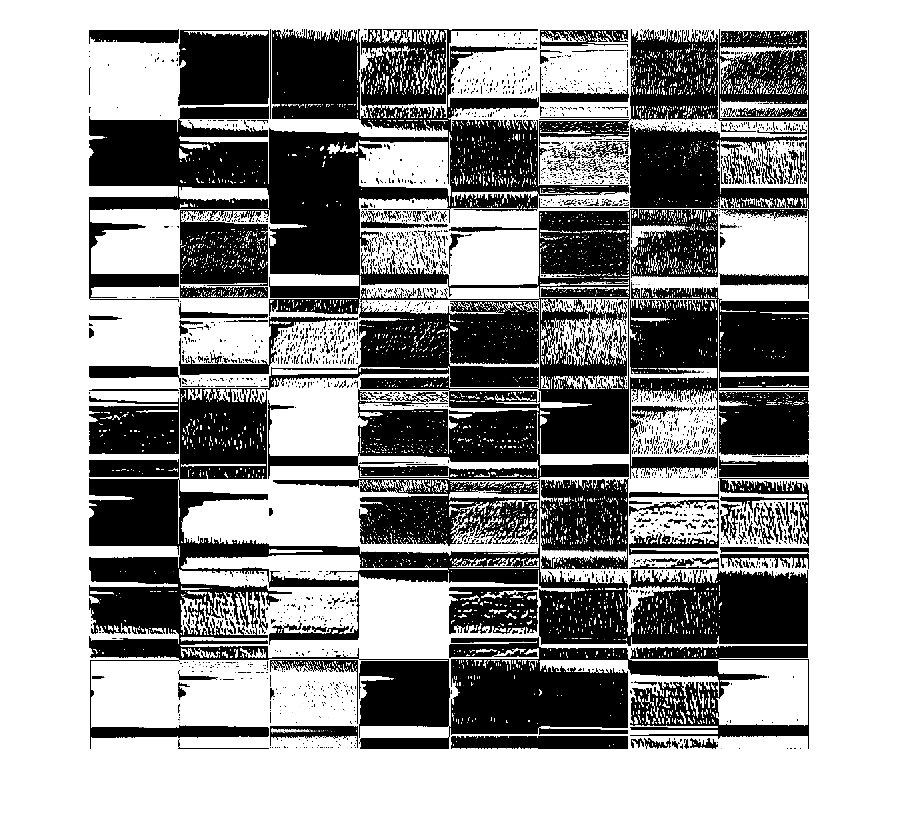

net=googlenet;
f=activations(net,a,"conv1-7x7_s2");
montage(f)

## Modify final layers for transfer learning

The fully connected layer and classification layer from GoogLeNet are replaced using deepNetworkDesigner(). Output size of new fullyconnected layer = 14 = number of instruments in this dataset.

deepNetworkDesigner()


## Train the network

Set the training options and train the network.

Training on single CPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:27 |        3.13% |       10.71% |       5.1310 |       3.3404 |          0.0010 |


|       5 |          50 |       00:13:24 |       38.28% |       48.81% |       1.6500 |       1.5536 |          0.0010 |


|      10 |         100 |       00:27:03 |       72.66% |       77.98% |       0.6704 |       0.6479 |          0.0010 |


|      15 |         150 |       00:40:05 |       91.41% |       89.29% |       0.2763 |       0.3493 |          0.0010 |


|      20 |         200 |       00:53:25 |       96.88% |       92.86% |       0.1086 |       0.2518 |          0.0010 |


|      25 |         250 |       01:06:29 |       97.66% |       93.45% |       0.1216 |       0.2267 |          0.0010 |


|      30 |         300 |       01:20:19 |       97.66% |       95.24% |       0.0857 |       0.1498 |          0.0010 |


|      35 |         350 |       01:33:28 |       99.22% |       95.24% |       0.0198 |       0.1766 |          0.0010 |


|      40 |         400 |       01:46:32 |       97.66% |       95.24% |       0.0739 |       0.1327 |          0.0010 |


|      45 |         450 |       01:59:31 |       99.22% |       98.81% |       0.0321 |       0.0523 |          0.0010 |


|      50 |         500 |       02:12:46 |      100.00% |       97.02% |       0.0026 |       0.1620 |          0.0010 |


|======================================================================================================================|


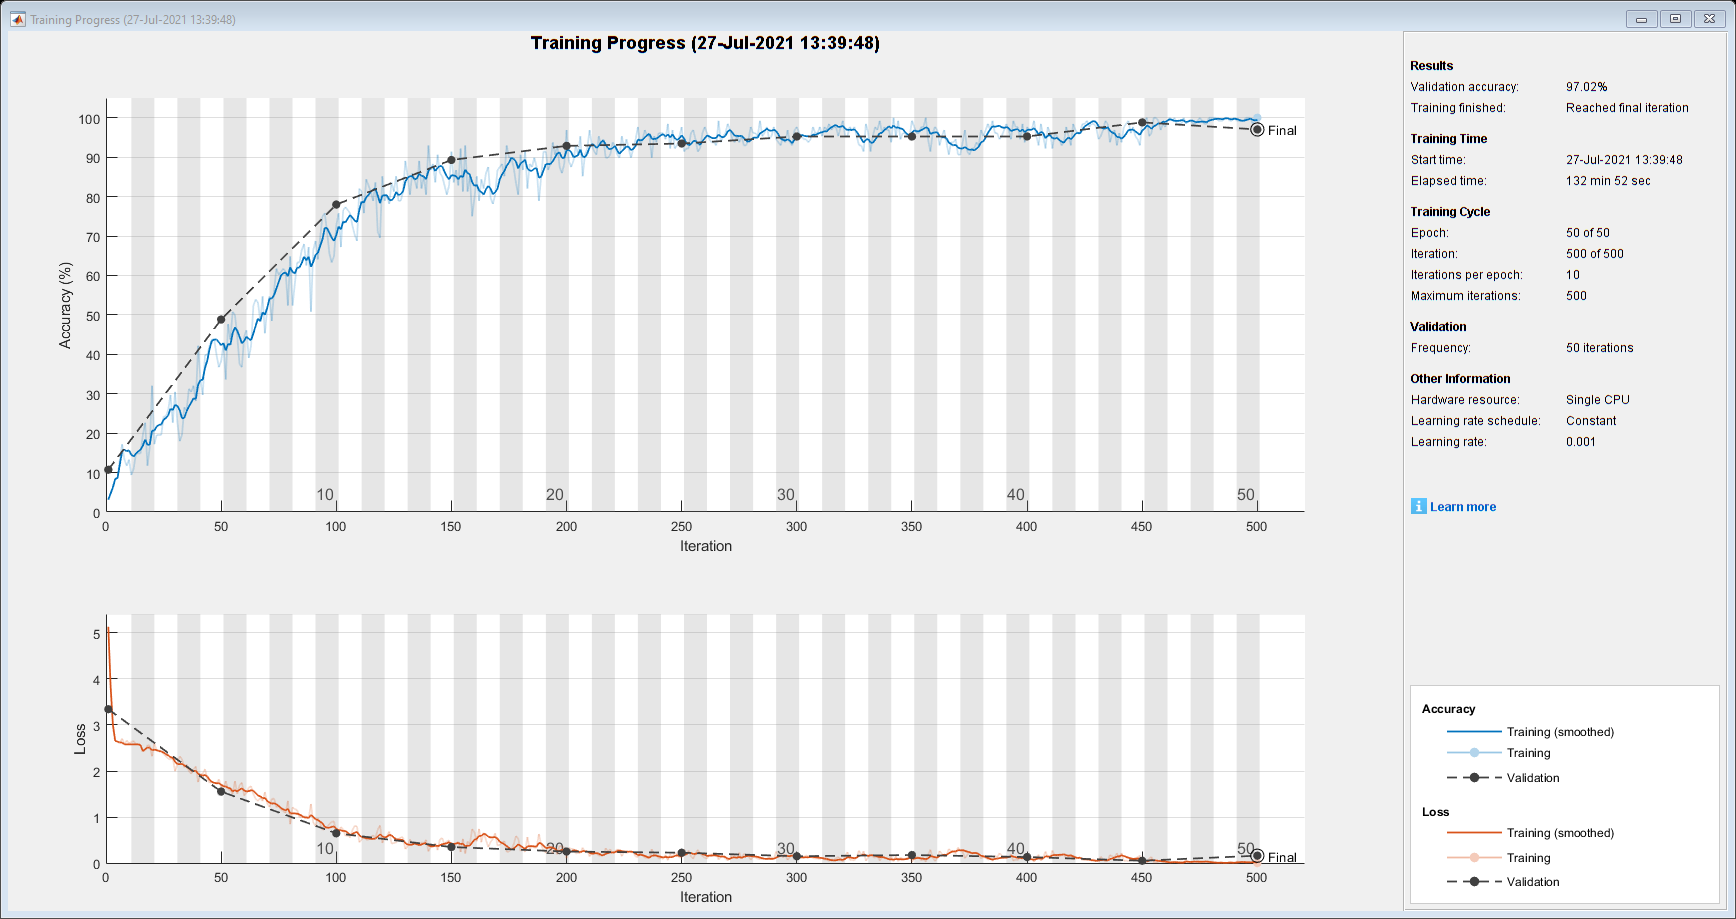

opt=trainingOptions("adam","Plots","training-progress","ValidationData",vlds,"MaxEpochs",50);
trl=trainNetwork(trds,lgraph_1,opt);

## Evaluate network

Calculate the accuracy on the test dataset.

pred=classify(trl,tsds);
nnz(pred==tsI.Labels)/numel(tsI.Labels)

ans = 0.9521

Plot confusion matrix

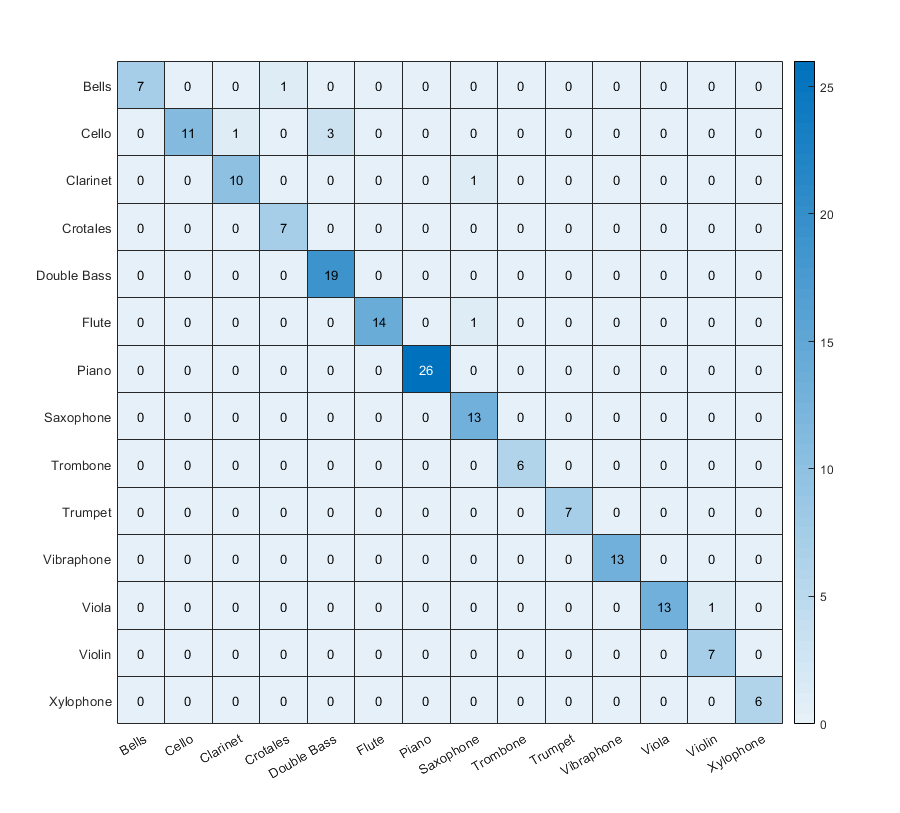

[cmap,clabel]=confusionmat(tsI.Labels,pred);
heatmap(clabel,clabel,cmap)

whos trl

  Name      Size               Bytes  Class         Attributes

  trl       1x1             24291440  DAGNetwork              

